defaultDir = 'M:\Bergles Lab Data\Papers\In Vivo Paper'; %change if in a different location
cd(defaultDir);
addpath(genpath('MATLAB Functions'));
cd('Supp Movies');
load('.\Data\IC_AC_videos_Sally.mat');



timeBef = 20;
timeAft = 30;
peak = 300;

rgb = zeros(300,300,3,timeBef+timeAft+1);
rgb(:,:,1,1:51) = ACvidHigh(:,:,peak-timeBef:peak+timeAft)*6;%/max(max(max(ACvidHigh)));

rgb(:,:,3,1:51) = ACvidLow(:,:,peak-timeBef:peak+timeAft);%/max(max(max(ACvidLow)));


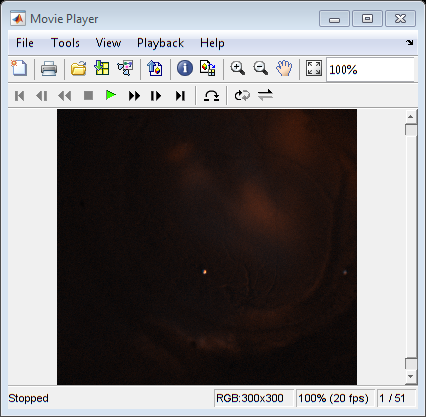

rgb(:,:,2,1:51) = rgb(:,:,1,1:51)*.3 + rgb(:,:,3,1:51)*.6;
%rgb = insertShape(rgb,'circle',[149 73 5])
figure; implay(rgb);

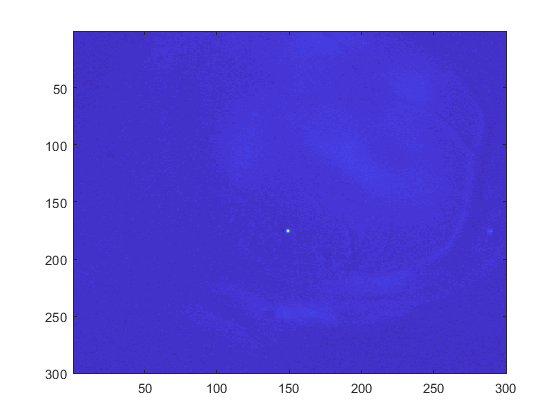


figure;imagesc(rgb(:,:,1,30))

timeBef = 15;
timeAft = 3;
peak = 300;

ACvidHigh_crop = ACvidHigh(1:end-45,26:end,:);
sizeAC = size(ACvidHigh_crop);
sizeIC = size(ICvidHigh);
timeBef = 15;
timeAft = 15;
high = zeros(sizeAC(1), sizeAC(2), 3, timeBef+timeAft+1);

high(:,:,1,:) = ACvidHigh_crop(:,:,peak-timeBef:peak+timeAft)*15;
high(sizeAC(1)-sizeIC(1)+1:end,1:sizeIC(2),1,:) = ICvidHigh(:,:,peak-timeBef:peak+timeAft)*25;
high(:,:,1,:) = high(:,:,1,:)/max(max(max(high(:,:,1))));
high(high >= 1) = 0.99;
high(high <= 0) = 0;
high(:,:,2,:) = high(:,:,1,:)*.6;
writeMovie('.\Data\Sally\high',high);

low = zeros(sizeAC(1), sizeAC(2), 3, timeBef+timeAft+1);
ACvidLow_crop = ACvidLow(1:end-45,26:end,:);
low(:,:,3,:) = ACvidLow_crop(:,:,peak-timeBef:peak+timeAft)*4;
low(sizeAC(1)-sizeIC(1)+1:end,1:sizeIC(2),3,:) = ICvidLow(:,:,peak-timeBef:peak+timeAft)*8;
low = low/max(max(max(max(low))));
low(:,:,2,:) = low(:,:,3,:)*.6;
low(low >= 1) = 0.99;
low(low<= 0) = 0;
writeMovie('.\Data\Sally\low',low);



timeBef = 15;
timeAft = 3;
ACvidHigh_crop = ACvidHigh(1:end-45,26:end,:);
sizeAC = size(ACvidHigh_crop);
sizeIC = size(ICvidHigh);

rgb = zeros(sizeAC(1), sizeAC(2), 3, timeBef+timeAft+1);

rgb(:,:,1,:) = ACvidHigh_crop(:,:,peak-timeBef:peak+timeAft)*15;
rgb(sizeAC(1)-sizeIC(1)+1:end,1:sizeIC(2),1,:) = ICvidHigh(:,:,peak-timeBef:peak+timeAft)*25;
rgb(:,:,2,:) = rgb(:,:,1,:)*.25;

ACvidLow_crop = ACvidLow(1:end-45,26:end,:);
rgb(:,:,3,:) = ACvidLow_crop(:,:,peak-timeBef:peak+timeAft)*4;
rgb(sizeAC(1)-sizeIC(1)+1:end,1:sizeIC(2),3,:) = ICvidLow(:,:,peak-timeBef:peak+timeAft)*8;
rgb(:,:,2,:) = rgb(:,:,2,:) + rgb(:,:,3,:)*.25;
rgb(:,:,1,:) = rgb(:,:,1,:)/max(max(max(rgb(:,:,1,:))));
rgb(:,:,3,:) = rgb(:,:,3,:)/max(max(max(rgb(:,:,3,:))));
rgb(rgb >= 1) = 0.99;
rgb(rgb<= 0) = 0;
writeMovie('.\Data\Sally\low_high',rgb);
%figure; implay(rgb);


function writeMovie(file,movie)
    v = VideoWriter(file,'Uncompressed AVI');
    v.FrameRate = 20;
    %v.Quality = 100;
    open(v);
    writeVideo(v,movie);
    close(v);
end